# Closed-loop transfer functions with feedback.m

This file focuses on simple feedback loops such as that shown in this figure here. We assume users are familiar with the basic algebra of feedback loops and focus on illustrating the use of MATLAB file ***feedback.m*** for creating and analysing these transfer functions. We assume users are familiar with the basic analysis tools such as covered in ***plotting_with_matlab.mlx, *** ***transferfunctions_and_poles.mlx ***and ***step_responses_with_matlab.mlx.***

This live script needs the control toolbox.

See website for more files like this.     [https://sites.google.com/sheffield.ac.uk/controleducation/mainindex](https://sites.google.com/sheffield.ac.uk/controleducation/mainindex)

A group of similar files can also be downloaded through MATLAB add-ons with the toolbox name:  **control101**

File written by J.A.Rossiter, University of Sheffield                         

## Table of contents

- Technical and mathematical background

- Example 1

- Example 2

- Example 3

- Plotting and overlaying closed-loop behaviour

## 1.Technical and mathematical background

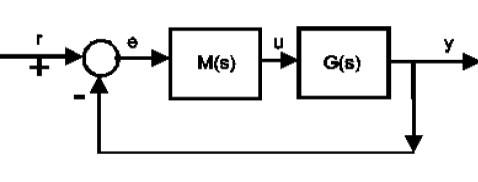

Using a standard feedback loop as above we have the closed-loop relationships:

$Y\left(s\right)=G_c \left(s\right)R\left(s\right)$ with   $G_c =\frac{\textrm{GM}}{1+\textrm{GM}}$

$U\left(s\right)=G_{\textrm{cu}} \left(s\right)R\left(s\right)$ with   $G_{\textrm{cu}} =\frac{M}{1+\textrm{GM}}$

$E\left(s\right)=G_{\textrm{ce}} \left(s\right)R\left(s\right)$ with   $G_{\textrm{ce}} =\frac{1}{1+\textrm{GM}}$

Of particular importance here is to note the generic rule for computing closed-loop transfer functions, that is:

***Gc = [FORWARD PATH]/[1 + RETURN PATH]***

As the loop above is the same for Y, U, and E they all have **a return path of GM**. However, the forward path from ***r*** to ***e*** is just 1, the forward path from ***r*** to ***u*** is M and the forward path from ***r*** to ***y*** is GM.

The MATLAB file** feedback.m** works in a similar  but different way in that it still uses the same '**forward path**', but critically, it then asks: what is the difference between the forward path and the return path?  In other words it uses the syntax:

**Gc = feedback(forward path, remainder)**        where           **forward path * remainder = return path**

$Y\left(s\right)=G_c \left(s\right)R\left(s\right)$ with   $G_c =\frac{\textrm{GM}}{1+\textrm{GM}}$;      Forward path is GM, remainder is 1.

$U\left(s\right)=G_{\textrm{cu}} \left(s\right)R\left(s\right)$ with   $G_{\textrm{cu}} =\frac{M}{1+\textrm{GM}}$;    Forward path is M, remainder is G.

$E\left(s\right)=G_{\textrm{ce}} \left(s\right)R\left(s\right)$ with   $G_{\textrm{ce}} =\frac{1}{1+\textrm{GM}}$;    Forward path is 1, remainder is GM.

**This will be clearer following the examples below. Try creating the answers on pen and paper to validate that you are using MATLAB correctly.**

## 2. Example 1

Consider the system and compensator given below. Users can change the code below to enter their own examples.

$G\left(s\right)=\frac{4}{s+2};\;\;M\left(s\right)=3$;            $G_c =\frac{\textrm{GM}\;}{1+\textrm{GM}\;}$ =  $\frac{12}{s+2+12}$;       $G_{\textrm{cu}} =\frac{M}{1+\textrm{GM}}\;\;$=  $\frac{3\left(s+2\right)}{s+14}$ 

Create these objects in MATLAB as follows:

disp('SECTION 2 examples below here')

SECTION 2 examples below here


G=tf(4,[1 2])

G =
 
    4
  -----
  s + 2
 
Continuous-time transfer function.



M=3

M = 3

Gc=feedback(G*M,1)

Gc =
 
    12
  ------
  s + 14
 
Continuous-time transfer function.



Gcu=feedback(M,G)

Gcu =
 
  3 s + 6
  -------
  s + 14
 
Continuous-time transfer function.



Gce=feedback(1,G*M)

Gce =
 
  s + 2
  ------
  s + 14
 
Continuous-time transfer function.




disp('END OF SECTION 2')

END OF SECTION 2


## 3. Example 2

Consider the system and compensator given below. Users can change the code below to enter their own examples.

$G\left(s\right)=\frac{5\left(s+4\right)}{s^4 +5s^3 +6s^2 +3s+2};\;\;M\left(s\right)=0\ldotp 6$;

Create these objects in MATLAB as follows

disp('SECTION 2 examples below here')

SECTION 2 examples below here


G=tf(5*[1 4],[1 5 6 3 2])

G =
 
            5 s + 20
  -----------------------------
  s^4 + 5 s^3 + 6 s^2 + 3 s + 2
 
Continuous-time transfer function.



M=0.7

M = 0.7000

Using same relationships as in example 1:   $G_c =\frac{\textrm{GM}}{1+\textrm{GM}}$,    $G_{\textrm{cu}} =\frac{M}{1+\textrm{GM}}$,    $G_{\textrm{ce}} =\frac{1}{1+\textrm{GM}}$

**Try creating the answers on pen and paper to validate that you are using MATLAB correctly.**

Gc=feedback(G*M,1)

Gc =
 
             3.5 s + 14
  --------------------------------
  s^4 + 5 s^3 + 6 s^2 + 6.5 s + 16
 
Continuous-time transfer function.



Gcu=feedback(M,G)

Gcu =
 
  0.7 s^4 + 3.5 s^3 + 4.2 s^2 + 2.1 s + 1.4
  -----------------------------------------
      s^4 + 5 s^3 + 6 s^2 + 6.5 s + 16
 
Continuous-time transfer function.



Gce=feedback(1,G*M)

Gce =
 
   s^4 + 5 s^3 + 6 s^2 + 3 s + 2
  --------------------------------
  s^4 + 5 s^3 + 6 s^2 + 6.5 s + 16
 
Continuous-time transfer function.



Is this a good or bad choice of M and why?

disp('END OF SECTION 3')

END OF SECTION 3


## 4. Example 3

Consider the system and compensator given below. Users can change the code below to enter their own examples.

$G\left(s\right)=\frac{4}{s+2};\;\;M\left(s\right)=\frac{3s+2}{s}$;

Create these objects in MATLAB as follows

disp('SECTION 4 examples below here')

SECTION 4 examples below here


G=tf(4,[1  2])

G =
 
    4
  -----
  s + 2
 
Continuous-time transfer function.



M= tf([3 2],[1 0])

M =
 
  3 s + 2
  -------
     s
 
Continuous-time transfer function.



Using same relationships as in example 1:   $G_c =\frac{\textrm{GM}}{1+\textrm{GM}}$,    $G_{\textrm{cu}} =\frac{M}{1+\textrm{GM}}$,    $G_{\textrm{ce}} =\frac{1}{1+\textrm{GM}}$

**Try creating the answers on pen and paper to validate that you are using MATLAB correctly.**

Gc=feedback(G*M,1)

Gc =
 
     12 s + 8
  --------------
  s^2 + 14 s + 8
 
Continuous-time transfer function.



Gcu=feedback(M,G)

Gcu =
 
  3 s^2 + 8 s + 4
  ---------------
  s^2 + 14 s + 8
 
Continuous-time transfer function.



Gce=feedback(1,G*M)

Gce =
 
    s^2 + 2 s
  --------------
  s^2 + 14 s + 8
 
Continuous-time transfer function.




disp('END OF SECTION 4')

END OF SECTION 4


## 5. Plotting and overlaying closed-loop behaviour

Thus section gives a simple example of determining and overlaying the input/output behaviour with 2 alternative compensators. It utilises the closed-loop transfer function computations illustrated in the earlier sections.

disp('SECTION 5 examples below here')

SECTION 5 examples below here


% define transfer functions
G=tf(6,[1  2  1])

G =
 
        6
  -------------
  s^2 + 2 s + 1
 
Continuous-time transfer function.



M1 = tf([2 1],[1 0])

M1 =
 
  2 s + 1
  -------
     s
 
Continuous-time transfer function.



M2 = 1.5

M2 = 1.5000

Gc1=feedback(G*M1,1)

Gc1 =
 
         12 s + 6
  ----------------------
  s^3 + 2 s^2 + 13 s + 6
 
Continuous-time transfer function.



Gcu1=feedback(M1,G)

Gcu1 =
 
  2 s^3 + 5 s^2 + 4 s + 1
  -----------------------
  s^3 + 2 s^2 + 13 s + 6
 
Continuous-time transfer function.



Gc2=feedback(G*M2,1)

Gc2 =
 
        9
  --------------
  s^2 + 2 s + 10
 
Continuous-time transfer function.



Gcu2=feedback(M2,G)

Gcu2 =
 
  1.5 s^2 + 3 s + 1.5
  -------------------
    s^2 + 2 s + 10
 
Continuous-time transfer function.



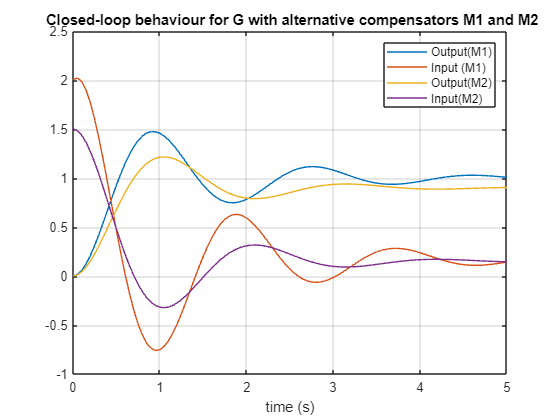

% collect step responses
[y1,t]=step(Gc1,5);
u1 = step(Gcu1,t);
y2 = step(Gc2,t);
u2 = step(Gcu2,t);
% plotting
plot(t,y1,t,u1,t,y2,t,u2);grid
xlabel('time (s)')
legend('Output(M1)','Input (M1)','Output(M2)','Input(M2)')
title(' Closed-loop behaviour for G with alternative compensators M1 and M2')